clear; clc;

% --- Parameters ---
data_folder = '/Users/manoharpaturi/Desktop/EEE S2 Proj/TestCasesLibrary_Measurement/Forced oscillation/Case 1F';
dt = 40 / 1200; % Time step (s)
expected_gens = 29; % Expected number of generators
fixed_rank = 29; % Force 29 modes
reg_param = 1e-2; % Regularization parameter for DMD

% --- Load Data ---
[Xraw, num_gens] = load_data(data_folder, dt);

Raw data size for rotor_speeds.csv: 1201 rows, 29 columns
Loaded rotor_speeds.csv: 1201 rows, 29 columns
Raw data size for rotor_angles.csv: 1201 rows, 29 columns
Loaded rotor_angles.csv: 1201 rows, 29 columns
Final Xraw: 29 signals, 2402 time steps


if num_gens ~= expected_gens
    error('Number of generators (%d) does not match expected (%d).', num_gens, expected_gens);
end
fprintf('Number of generators: %d\n', num_gens);

Number of generators: 29



% --- Prepare DMD Inputs ---
Xraw = Xraw - mean(Xraw, 2);
X1 = Xraw(:, 1:end-1);
X2 = Xraw(:, 2:end);
t = (0:size(Xraw, 2)-1) * dt;

% --- Rank Selection ---
[U, S, V] = svd(X1, 'econ');
singular_values = diag(S);
r = min(fixed_rank, length(singular_values));
if r < fixed_rank
    warning('Only %d singular values available; using rank %d.', length(singular_values), r);
end
fprintf('Selected rank for DMD: %d\n', r);

Selected rank for DMD: 29



--- Exact DMD ---


Reconstruction Error: 4.991773e+08


Modes (29 total):


    frequency    damping_ratio      energy      amplitude     dominant_generator
    _________    _____________    __________    __________    __________________

           0               1      1.7542e-05     0.0041883            16        
           0               1       0.0002167      0.014721            16        
           0              -1           26218        161.92            16        
     0.10882          0.3819        0.011353       0.10655            23        
     0.10882          0.3819        0.011353       0.10655            23        
     0.36173         0.15492       0.0004431       0.02105            16        
     0.36173         0.15492       0.0004431       0.02105            16        
      0.3766        0.004061      8.7604e-05     0.0093597            23        
      0.3766       

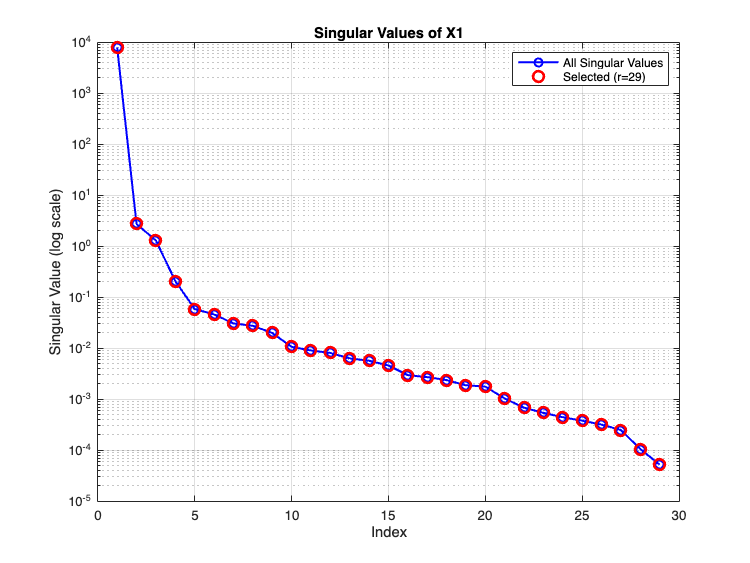

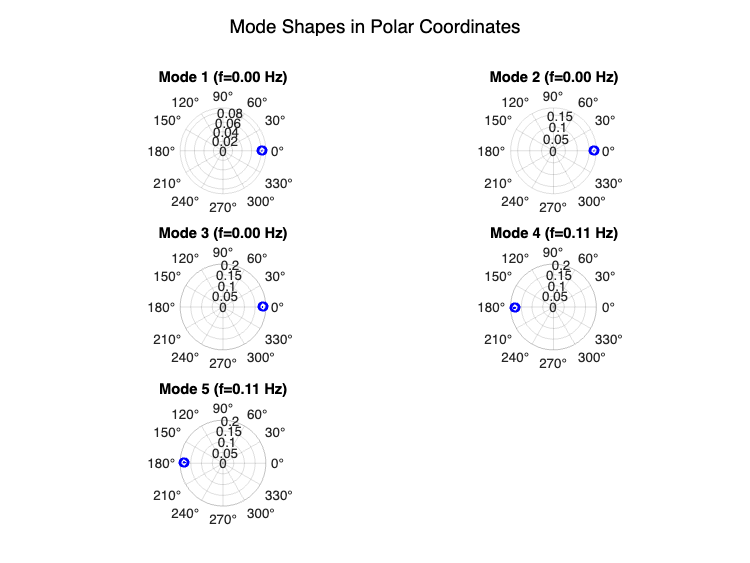

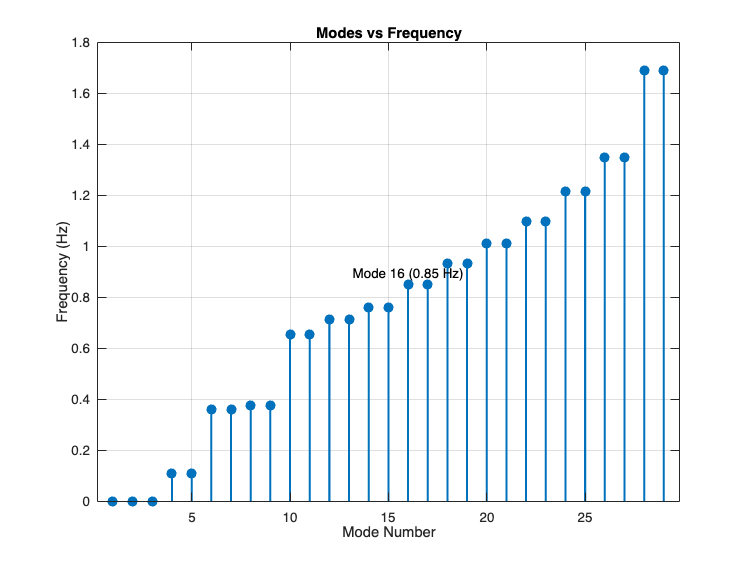


% --- Exact DMD ---
try
    [U, S, V] = svd(X1, 'econ');
    Ur = U(:, 1:r); Sr = S(1:r, 1:r); Vr = V(:, 1:r);
    Atilde = Ur' * X2 * Vr / Sr;
    Atilde_reg = Atilde + reg_param * eye(size(Atilde));
    [Phi_reg, Lambda_reg] = eig(Atilde_reg);
    Phi = X2 * Vr / Sr * Phi_reg;
    lambda = diag(Lambda_reg);
    b = pinv(Phi) * X1(:, 1);
    assert(size(Phi, 2) == length(b), 'Exact DMD: Phi and b dimensions mismatch');
    assert(length(b) == length(lambda), 'Exact DMD: b and lambda dimensions mismatch');
    X_recon = zeros(size(Xraw));
    for k = 1:length(t)
        X_recon(:, k) = real(Phi * (b .* lambda.^(k-1)));
    end
    error_exact = norm(Xraw - X_recon, 'fro') / norm(Xraw, 'fro');
    mode_props_exact = analyze_modes(Phi, lambda, abs(imag(log(lambda)/dt))/(2*pi), ...
        -real(log(lambda)/dt)./abs(log(lambda)/dt), b, num_gens);
catch e
    fprintf('Error in Exact DMD: %s\n', e.message);
    error_exact = NaN;
    mode_props_exact = [];
end

% --- Display Modes ---
if ~isnan(error_exact)
    fprintf('\n--- Exact DMD ---\n');
    fprintf('Reconstruction Error: %.6e\n', error_exact);
    fprintf('Modes (%d total):\n', height(mode_props_exact));
    dominant_gen = zeros(height(mode_props_exact), 1);
    for j = 1:height(mode_props_exact)
        mode_shape = mode_props_exact.mode_shape{j}(1:num_gens);
        participation = calc_participation(mode_shape, num_gens);
        [~, max_gen] = max(participation);
        dominant_gen(j) = max_gen;
    end
    mode_props_exact.dominant_generator = dominant_gen;
    disp(mode_props_exact(:, {'frequency', 'damping_ratio', 'energy', 'amplitude', 'dominant_generator'}));
    
    % --- Plotting ---
    % Singular Values Plot
    figure;
    semilogy(singular_values, 'bo-', 'LineWidth', 1.5);
    hold on;
    semilogy(singular_values(1:r), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    title('Singular Values of X1', 'FontSize', 14);
    xlabel('Index', 'FontSize', 12);
    ylabel('Singular Value (log scale)', 'FontSize', 12);
    legend('All Singular Values', sprintf('Selected (r=%d)', r));
    grid on;
    set(gca, 'FontSize', 10);
    
    % Mode Shapes in Polar Coordinates (first few modes)
    num_modes_to_plot = min(5, height(mode_props_exact)); % Plot up to 5 modes
    figure;
    for j = 1:num_modes_to_plot
        subplot(ceil(num_modes_to_plot/2), 2, j);
        mode_shape = mode_props_exact.mode_shape{j}(1:num_gens);
        theta = angle(mode_shape); % Phase in radians
        rho = abs(mode_shape); % Magnitude
        polarplot(theta, rho, 'bo-', 'LineWidth', 1.5);
        title(sprintf('Mode %d (f=%.2f Hz)', j, mode_props_exact.frequency(j)), 'FontSize', 10);
        pax = gca;
        pax.ThetaAxisUnits = 'degrees';
        pax.FontSize = 10;
    end
    sgtitle('Mode Shapes in Polar Coordinates', 'FontSize', 14);
    
    % Modes vs Frequency Plot
    figure;
    mode_numbers = 1:height(mode_props_exact);
    stem(mode_numbers, mode_props_exact.frequency, 'filled', 'LineWidth', 1.5, 'MarkerSize', 6);
    title('Modes vs Frequency', 'FontSize', 14);
    xlabel('Mode Number', 'FontSize', 12);
    ylabel('Frequency (Hz)', 'FontSize', 12);
    grid on;
    % Label the mode closest to 0.86 Hz
    [~, idx_086] = min(abs(mode_props_exact.frequency - 0.86));
    text(mode_numbers(idx_086), mode_props_exact.frequency(idx_086)*1.05, ...
         sprintf('Mode %d (%.2f Hz)', idx_086, mode_props_exact.frequency(idx_086)), ...
         'FontSize', 10, 'HorizontalAlignment', 'center');
    set(gca, 'FontSize', 10);
else
    fprintf('\n--- Exact DMD ---\n');
    fprintf('Failed to compute modes.\n');
end


% --- Helper Functions ---

function [Xraw, num_gens] = load_data(data_folder, dt)
    file_names = {'rotor_speeds.csv', 'rotor_angles.csv'};
    Xraw = [];
    num_gens = 0;
    
    for i = 1:length(file_names)
        file_path = fullfile(data_folder, file_names{i});
        if exist(file_path, 'file')
            data = readmatrix(file_path, 'NumHeaderLines', 1);
            if size(data, 2) < 2
                warning('File %s has insufficient columns.', file_names{i});
                continue;
            end
            data = data(:, 2:end);
            fprintf('Raw data size for %s: %d rows, %d columns\n', file_names{i}, size(data, 1), size(data, 2));
            if contains(file_names{i}, 'rotor_speeds', 'IgnoreCase', true)
                num_gens = size(data, 2);
                mean_spd = mean(data(:));
                if mean_spd < 1
                    warning('Rotor speeds appear to be in per-unit (mean = %.4f). Converting to Hz assuming 60 Hz base.', mean_spd);
                    data = data * 60;
                end
            else
                max_val = max(abs(data(:)));
                if max_val > 0
                    data = data / max_val;
                else
                    data = zeros(size(data));
                end
            end
            Xraw = [Xraw; data];
            fprintf('Loaded %s: %d rows, %d columns\n', file_names{i}, size(data, 1), size(data, 2));
        else
            warning('File %s not found.', file_path);
        end
    end
    
    if isempty(Xraw)
        error('No data loaded.');
    end
    
    Xraw = Xraw';
    fprintf('Final Xraw: %d signals, %d time steps\n', size(Xraw, 1), size(Xraw, 2));
end

function mode_props = analyze_modes(Phi, lambda, freq_Hz, damping_ratio, b, num_gens)
    num_modes = length(lambda);
    mode_energy = abs(b).^2;
    amplitude = abs(b); % Amplitude is the magnitude of b
    
    mode_shapes = cell(num_modes, 1);
    for i = 1:num_modes
        mode_shapes{i} = Phi(:, i);
    end
    
    mode_props = table(...
        freq_Hz(:), damping_ratio(:), mode_energy(:), amplitude(:), mode_shapes, ...
        'VariableNames', {'frequency', 'damping_ratio', 'energy', 'amplitude', 'mode_shape'});
    
    mode_props = sortrows(mode_props, 'frequency');
end

function participation = calc_participation(mode_shape, num_gens)
    if length(mode_shape) < num_gens
        error('Mode shape length (%d) less than num_gens (%d).', length(mode_shape), num_gens);
    end
    mode = mode_shape(1:num_gens);
    norm_val = norm(mode);
    if norm_val > 1e-6
        normalized = mode / norm_val;
    else
        normalized = zeros(size(mode));
    end
    participation = abs(normalized).^2;
end
